**Statistical Methods **

**Luis Mario Bres Castro**

**Lab 4: Plot Amplitude Modulated Sinosoid Signal **

%Signal Parameters
A=10; 
f0=150; 
f1=4;
psi0=45;

%Time samples 
a1=30;
a2=30;
a3=20;
maxFreq=a1+2*a2+3*a3;
samplFreq=5*maxFreq;
samplIntrvl=1/samplFreq;
t=0:samplIntrvl:1;

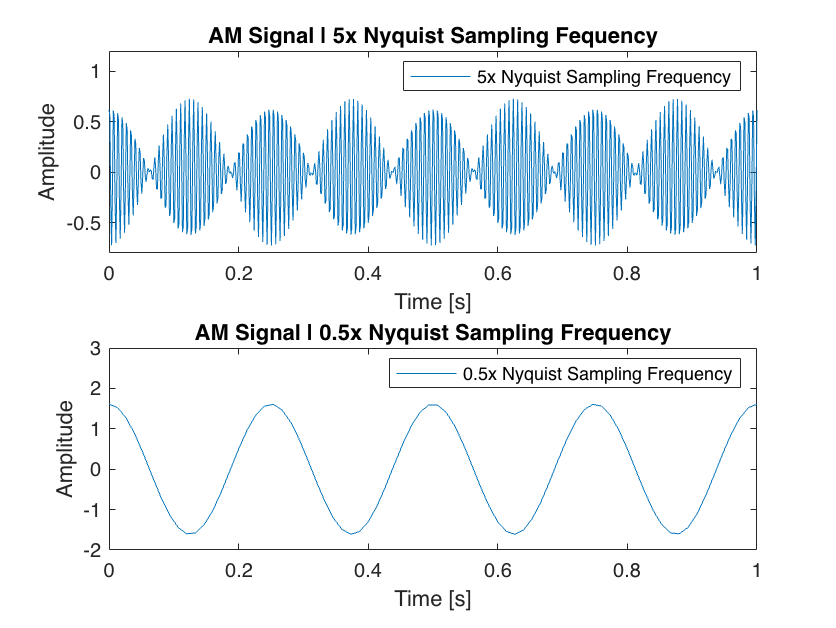

%Generate Signal

SigVec = AMSigGen(t,A,f0,f1,psi0);

%Plot the signal for 5x Nyquist sampling frequency
subplot(2,1,1)
plot(t,SigVec)
ylim([-0.8 1.2])
legend({'5x Nyquist Sampling Frequency'},'Location','northeast')
title('AM Signal | 5x Nyquist Sampling Fequency')
xlabel('Time [s]')
ylabel('Amplitude')

%Time samples and Plot of signal for 0.5x Nyquist sampling frequency
subplot(2,1,2)
samplFreq1=0.5*maxFreq;
samplIntrvl1=1/samplFreq1;
t1=0:samplIntrvl1:1;
SigVec1 = AMSigGen(t1,A,f0,f1,psi0);

plot(t1,SigVec1)
ylim([-2 3])
legend({'0.5x Nyquist Sampling Frequency'},'Location','northeast')
title('AM Signal | 0.5x Nyquist Sampling Frequency')
xlabel('Time [s]')
ylabel('Amplitude')